clear
clf
%1st problem (f)

a = 1.115 * 10^-3; %Thermal diffusivity(m^2/s)
U = 50; %Initial temperature (K)
L = 1; %Length of the domain (m)
x = linspace(0,1,1000);
n = 1;

t = 0;
e = exp(-a*t*((pi/L)^2));
c = cos((pi.*x)./L);
T = (U/2).*(1 + (e.*c));

t_2 = 25;
e_2 = exp(-a*t_2*((pi/L)^2));
c_2 = cos((pi.*x)./L);
T_2 = (U/2).*(1 + (e_2.*c_2));

t_3 = 100;
e_3 = exp(-a*t_3*((pi/L)^2));
c_3 = cos((pi.*x)./L);
T_3 = (U/2).*(1 + (e_3.*c_3));

t_4 = 1000;
e_4 = exp(-a*t_4*((pi/L)^2));
c_4 = cos((pi.*x)./L);
T_4 = (U/2).*(1 + (e_4.*c_4));

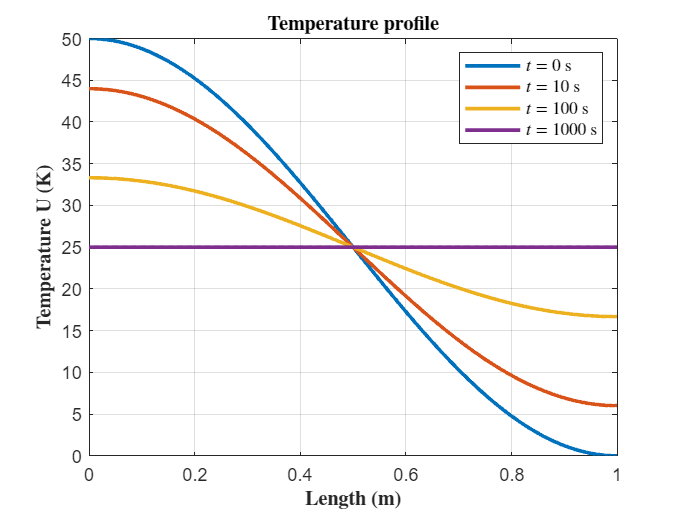

%Plots
h1 = plot(x, T,'LineWidth', 2);
grid on
ylabel('$\textbf{Temperature U (K)}$','Interpreter', 'latex')
xlabel('$\textbf{Length (m)}$', 'Interpreter', 'latex')
title('$\textbf{Temperature profile}$', 'Interpreter', 'latex');
hold on
h2 = plot(x, T_2,'LineWidth', 2);
h3 = plot(x, T_3,'LineWidth', 2);
h4 = plot(x, T_4,'LineWidth', 2);
legend([h1, h2, h3, h4], '$t = 0$ s', '$t = 10$ s', '$t = 100$ s', '$t = 1000$ s', 'Interpreter', 'latex');

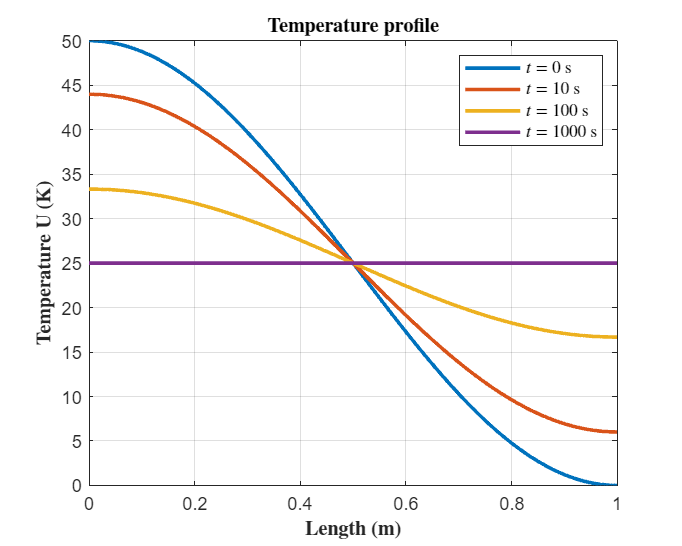

%Saving plot
outputFileName = 'Problem_1_f.png';
figureHandle = gcf;
figureWidth = 1000; % in pixels
figureHeight = 800; % in pixels
set(figureHandle, 'Position', [100, 100, figureWidth, figureHeight]); 
print(figureHandle, outputFileName, '-dpng', '-r600');